clearvars;
load("BackupData.mat")

%Creates tables to display the results
%The table is done this way to allow for
%quicker table modifications.
disp('Triangle Arm / Model 1 Table');

Triangle Arm / Model 1 Table


disp(Show1);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety       Cost       Total_Cost    Cost_mass_total
    _______________________________    ______________    ______________    __________    __________    __________    ________________    __________    __________    _______________

    "Carbon Fiber Composite (CFRP)"       0.042778          0.82889          "Yes"       0.00088702    2.4564e+07         24.426            0.72189        2.8875          13.65    
    "Aluminum Alloy"                      0.072189          0.71125          "Yes"       0.00089039    2.4322e+07   


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Circle Arm / Model 2 Table');

Circle Arm / Model 2 Table


disp(Show2);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety       Cost       Total_Cost    Cost_mass_total
    _______________________________    ______________    ______________    __________    __________    __________    ________________    __________    __________    _______________

    "Carbon Fiber Composite (CFRP)"       0.024813          0.90075          "Yes"       0.00021511    1.5817e+07         37.934            0.60804        2.4322         4.3238    
    "Aluminum Alloy"                      0.041873          0.83251          "Yes"       0.00021558    1.5094e+07   


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Beam Arm / Model 3 Table');

Beam Arm / Model 3 Table


disp(Show3);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety      Cost      Total_Cost    Cost_mass_total
    _______________________________    ______________    ______________    __________    __________    __________    ________________    ________    __________    _______________

    "Carbon Fiber Composite (CFRP)"       0.026745          0.89302          "Yes"       0.00097521    5.6122e+07         10.691            0.648        2.592          4.608     
    "Aluminum Alloy"                      0.045133          0.81947          "Yes"       0.00097876    5.5185e+07         


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Lattice Arm / Model 4 Table');

Lattice Arm / Model 4 Table


disp(Show4);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety      Cost       Total_Cost    Cost_mass_total
    _______________________________    ______________    ______________    __________    __________    __________    ________________    _________    __________    _______________

    "Carbon Fiber Composite (CFRP)"       0.091297          0.63481          "Yes"       5.7522e-05    7.8082e+06         76.842            3.7137       14.855          26.409    
    "Aluminum Alloy"                       0.15406          0.38375          "No"        5.6408e-05    7.5645e+06      


%Max_Displacement = max(Result.Displacement.Magnitude)
%Max_Stress = max(Result.VonMisesStress)
%FoS = materials(1).yieldStrength_Pa/Max_Stress

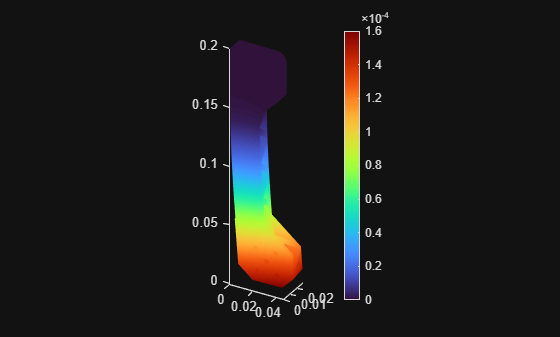

% Data to visualize
meshData = Model_4_result_GFRP.Mesh;
nodalData = Model_4_result_GFRP.Displacement.Magnitude;
deformationData = Model_4_result_GFRP.Displacement;

% Create PDE result visualization
resultViz2 = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",93.7574, ...
    "ColorLimits",[0 0.00016]);


% Clear temporary variables
clearvars meshData nodalData deformationData